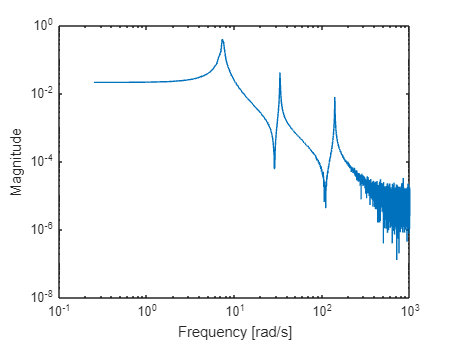

clear
addpath("frffit"); addpath("Assignments")
load("frfdata.mat")

bodeplm(hz,H1)

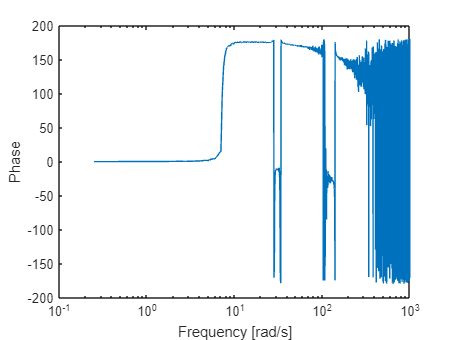

bodeplp(hz,H1)

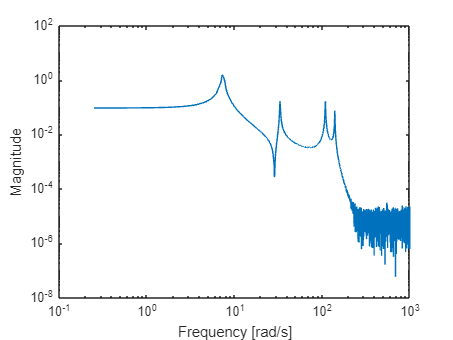


bodeplm(hz,H2)

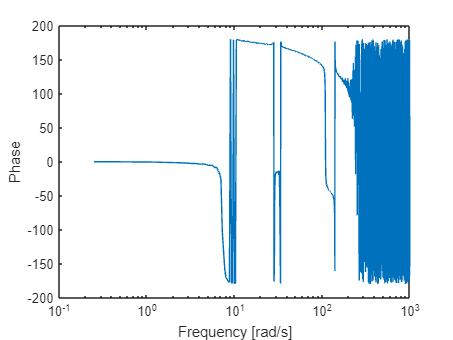

bodeplp(hz,H2)

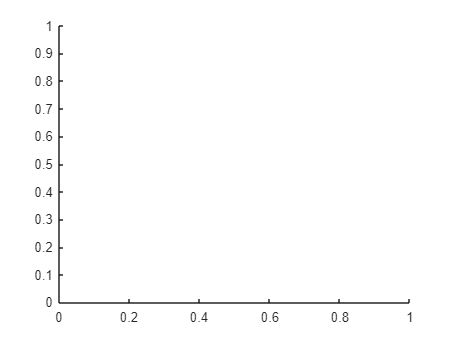

figure()
hold on

[num, den] = (frfit(H1,hz,[1+2+4, 1 + 1 + 4, 0], 1));

Frequency vector is linear; WF is therefore adjusted.
initial estimate of FRQLS
determination of initial errors
 
Building original data matrix
 
Start output error iterations
OE iteration 1; a/m-re of 1/den: 0.99364 215.6429
OE iteration 2; a/m-re of 1/den: 0.98404 63.5967
OE iteration 3; a/m-re of 1/den: 0.90165 22.0725
OE iteration 4; a/m-re of 1/den: 0.92728 11.6809


OE iteration 5; a/m-re of 1/den: 0.96535 1.1366


OE iteration 6; a/m-re of 1/den: 0.989 4.7858


OE iteration 7; a/m-re of 1/den: 0.88475 2.3671


OE iteration 8; a/m-re of 1/den: 0.22168 0.31614


OE iteration 9; a/m-re of 1/den: 0.059841 0.09106


OE iteration 10; a/m-re of 1/den: 0.004346 0.0066309


OE iteration 11; a/m-re of 1/den: 0.00032837 0.00049823


OE iteration 12; a/m-re of 1/den: 2.8222e-05 4.2284e-05


OE iteration 13; a/m-re of 1/den: 2.4082e-06 3.4759e-06


OE iteration 14; a/m-re of 1/den: 2.1436e-07 3.9894e-07


OE iteration 15; a/m-re of 1/den: 2.1955e-08 5.0455e-08
Linear step on numerator coefficients
norm = euclidian norm; error e(w):=sF(w)-s(w);
average relative error of s (are) := norm(e)/norm(sF)
maximum relative error of s (mre) := max(abs(e)./abs(sF)
are mre for the consecutive iterations:
   2.0299e+01   6.8992e+04
   3.0732e-01   7.4203e+01

 


H = tf(num,den)

H =
 
              92.34 s^5 - 1.802e04 s^4 + 4.613e07 s^3 - 6.962e08 s^2 + 1.398e12 s - 6.595e12
  -------------------------------------------------------------------------------------------------------
  s^7 + 6.484e-14 s^6 + 8.124e05 s^5 - 4.301e06 s^4 + 3.482e10 s^3 - 2.269e11 s^2 + 6.966e13 s - 3.217e14
 
Continuous-time transfer function.


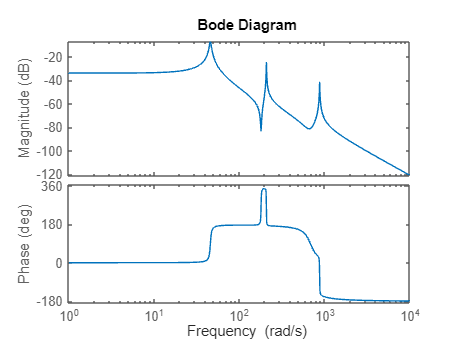


figure()
bode(H)


[num,den] = (frsfit(H2,hz,[2+2+2+6, 2+4+2, 0], 1));

Frequency vector is linear; WF is therefore adjusted.
initial estimate of FRQLS
determination of initial errors
 
Building original data matrix
 
Start output error iterations
OE iteration 1; a/m-re of 1/den: 1 1.0048
OE iteration 2; a/m-re of 1/den: 1.0012 4073.1618


OE iteration 3; a/m-re of 1/den: 1.004 124.7913


OE iteration 4; a/m-re of 1/den: 1.8213 4609.2666


OE iteration 5; a/m-re of 1/den: 0.92147 32.3684


OE iteration 6; a/m-re of 1/den: 1.0131 31.7697


OE iteration 7; a/m-re of 1/den: 0.89707 24.2776


OE iteration 8; a/m-re of 1/den: 0.86132 20.8841


OE iteration 9; a/m-re of 1/den: 0.92489 31.4794


OE iteration 10; a/m-re of 1/den: 0.99076 32.4868


OE iteration 11; a/m-re of 1/den: 1.6078 1375.4156


OE iteration 12; a/m-re of 1/den: 1.0267 14.1685


OE iteration 13; a/m-re of 1/den: 0.95682 1.7143


OE iteration 14; a/m-re of 1/den: 0.61327 2.5363


OE iteration 15; a/m-re of 1/den: 0.19179 0.26671


OE iteration 16; a/m-re of 1/den: 0.01147 0.015938


OE iteration 17; a/m-re of 1/den: 0.0022181 0.0030932


OE iteration 18; a/m-re of 1/den: 0.00017434 0.00024294


OE iteration 19; a/m-re of 1/den: 2.53e-05 3.5279e-05


OE iteration 20; a/m-re of 1/den: 2.4111e-06 3.3609e-06


OE iteration 21; a/m-re of 1/den: 3.0554e-07 4.2597e-07


OE iteration 22; a/m-re of 1/den: 3.1923e-08 4.4491e-08
Linear step on numerator coefficients
norm = euclidian norm; error e(w):=sF(w)-s(w);
average relative error of s (are) := norm(e)/norm(sF)
maximum relative error of s (mre) := max(abs(e)./abs(sF)
are mre for the consecutive iterations:
   2.3801e+01   1.7781e+07
   2.8355e-01   2.9075e+00

 


H = tf(num,den)

H =
 
                                                        2.106e20 s^4 + 2.687e23 s^3 + 1.239e26 s^2 + 8.831e27 s + 3.775e30
  -------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^12 + 3757 s^11 + 7.058e06 s^10 + 9.05e09 s^9 + 9.093e12 s^8 + 6.974e15 s^7 + 4.034e18 s^6 + 1.816e21 s^5 + 6.139e23 s^4 + 7.088e25 s^3 + 2.051e28 s^2 + 1.821e29 s + 4.009e31
 
Continuous-time transfer function.


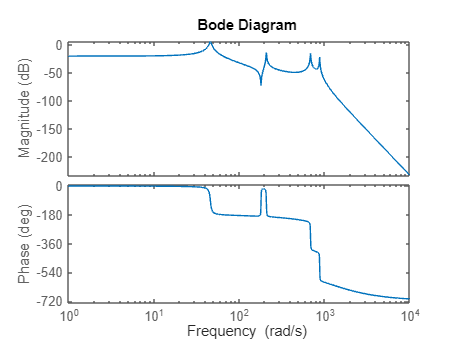


figure()
bode(H)